clear
clc


load sub_network_label.mat
load label.mat

[sub_net_list, sub_net_ind] = sort(sub_network_label, "ascend");
% healthy control
label_NC = find(label == 2);
load Data_net.mat



% calculate net
net = [];

% net HAN
net(:, :, 1) = mean(net_act(:, :, label_NC), 3);
net(:, :, 1) = threshold_net(net(:, :, 1), 0.1, "high", "binary");

% net LAN
net(:, :, 2) = mean(net_act(:, :, label_NC), 3);
net(:, :, 2) = threshold_net(net(:, :, 2), 0.1, "low", "binary");

% net DFN
net(:, :, 3) = mean(net_sta(:, :, label_NC), 3);
net(:, :, 3) = threshold_net(net(:, :, 3), 0.1, "high", "binary");

net = net(sub_net_ind, sub_net_ind, :);

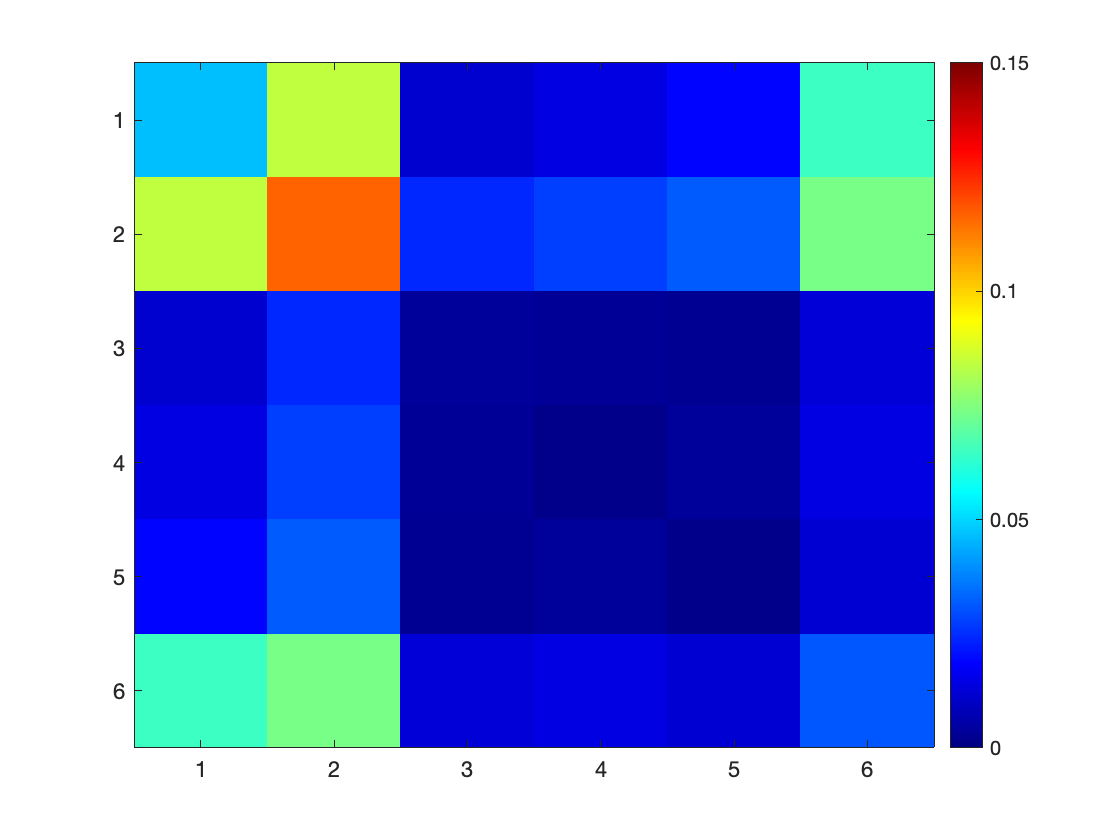

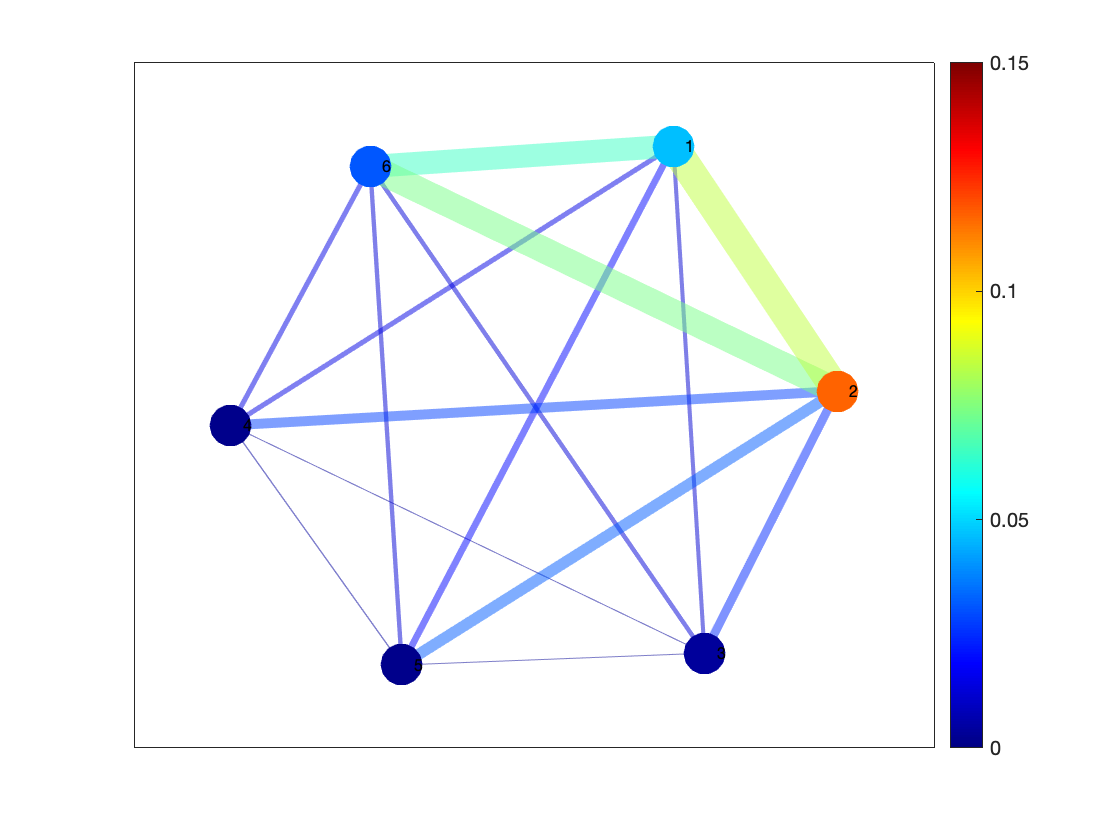

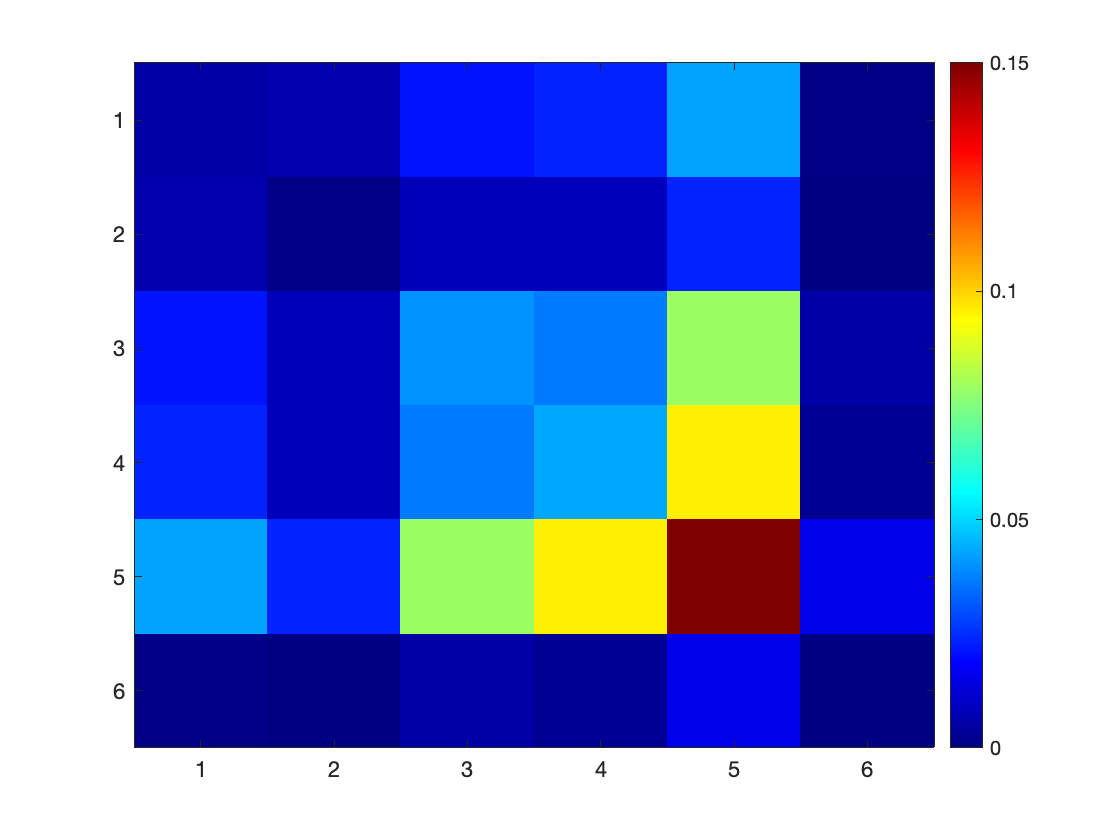

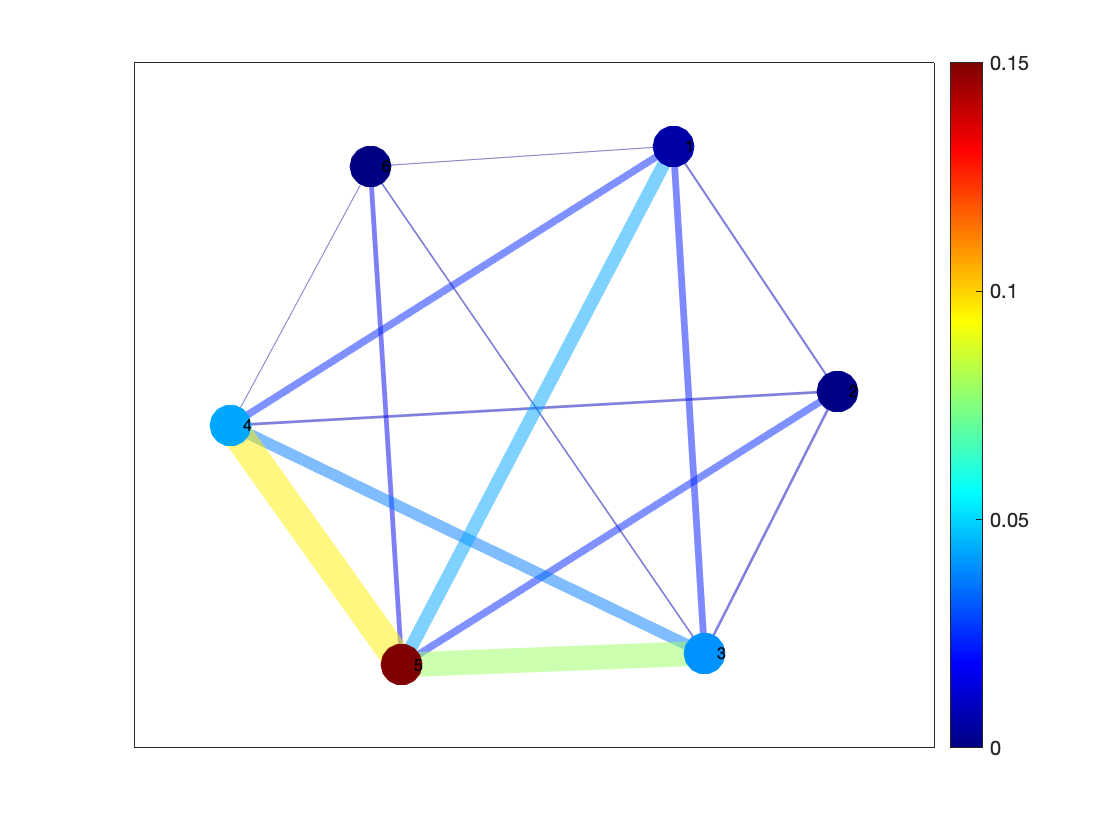

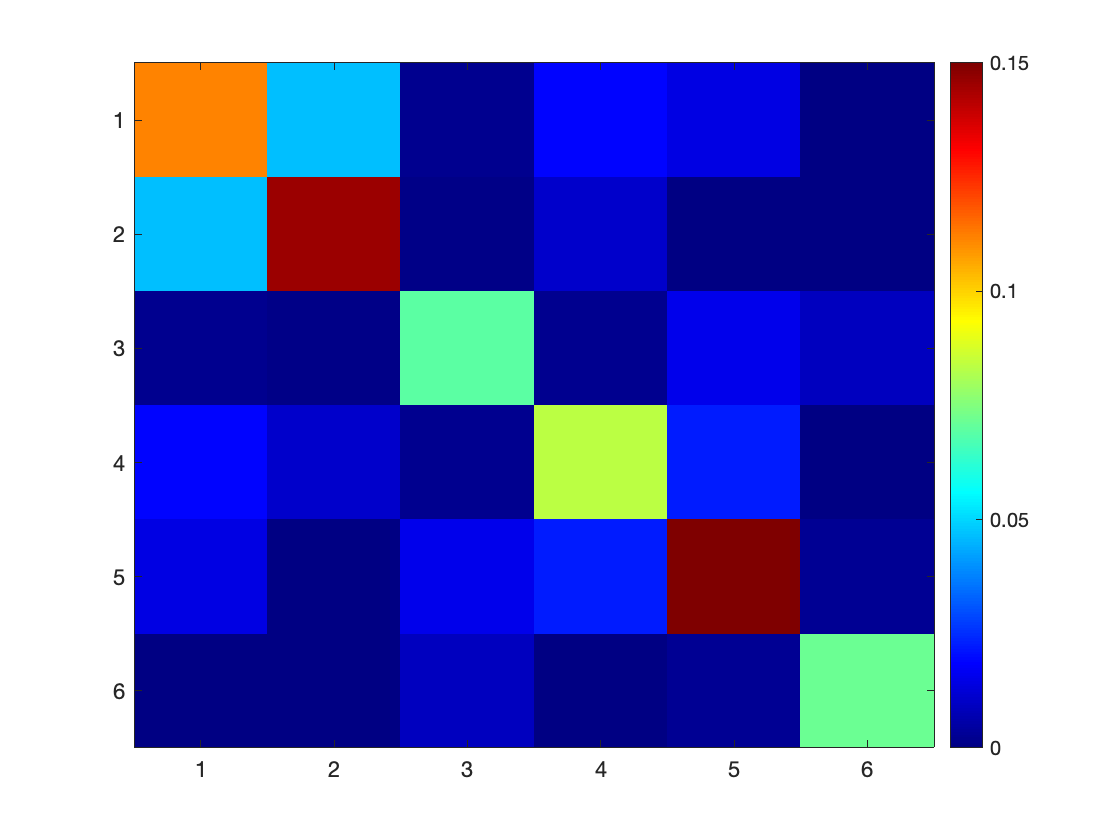

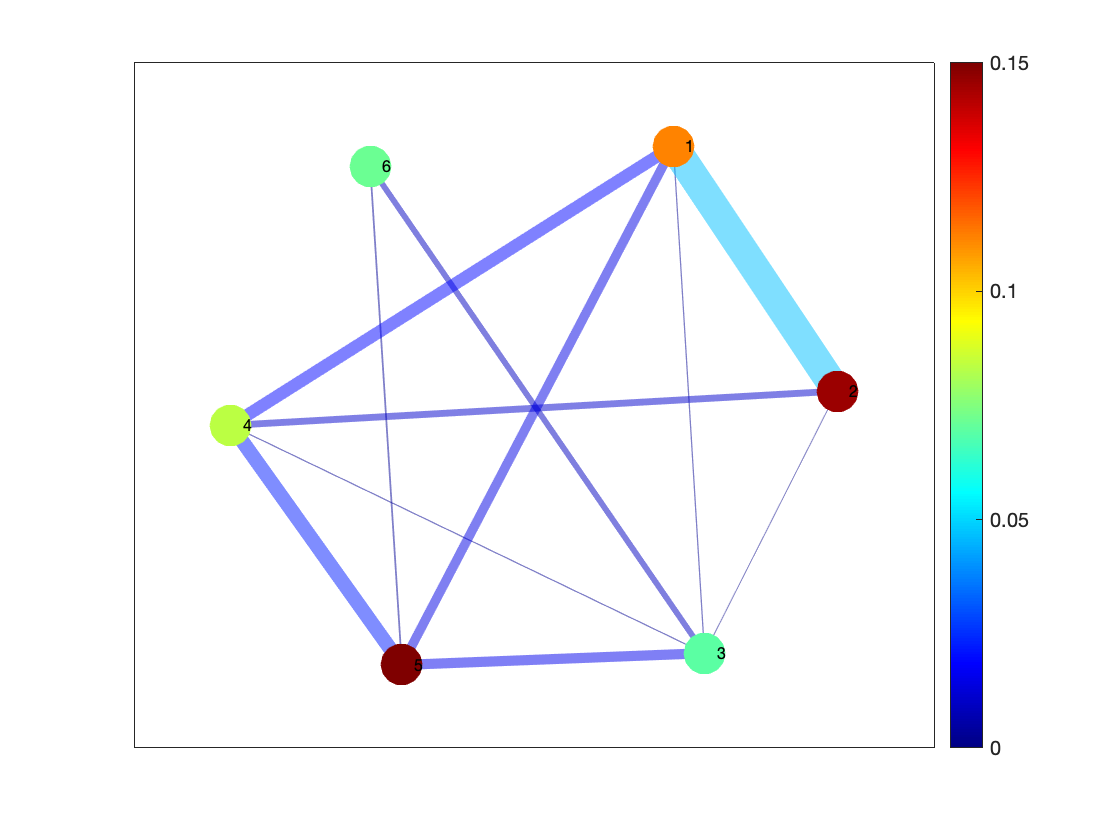

% plot network

map = "jet";
x = [0.802385749219495,1.760315807155634,0.984548013597186,-1.787499058748782,-0.787506726261186,-0.972243784962346];
y = [1.597617121284458,0.102069992210448,-1.497019440251274,-0.106709857894361,-1.568755921223343,1.472798105874071];

for i = 1:3 % 1 HAN, 2 LAN, 3 DFN
    
    net_data = net(:, :, i);
    
    net_mean = mat2cell(net_data, [32 33 22 21 34 18], [32 33 22 21 34 18]);
    net_mean = cellfun(@(x) sum(x, "all"), net_mean, "UniformOutput", false);
    net_mean = cell2mat(net_mean);
    
    % plot matrix
    figure
    h = imagesc(net_mean ./ sum(net_mean, 'all'));
    colormap(map)
    colorbar
    caxis([0 0.15])
    
    % plot graph
    figure
    G = graph(net_mean, 'omitselfloops');
    node_weight = net_mean(logical(eye(6))) ./ sum(net_mean, "all");
    LWidths = 15 * G.Edges.Weight / max(G.Edges.Weight);
    h = plot(G, 'EdgeCData', G.Edges.Weight ./ sum(net_mean, 'all'), ...
        "MarkerSize", 10, 'LineWidth', LWidths,'Layout','force', "NodeCData", node_weight);
    colormap(map)
    highlight(h, [1:6])
    
    h.XData = x;
    h.YData = y;
    colorbar
    caxis([0 0.15])
    
    % count distribution
    con(:, i) = [sum(net_mean(~logical(eye(6)))) sum(net_mean(logical(eye(6))))];
    
end

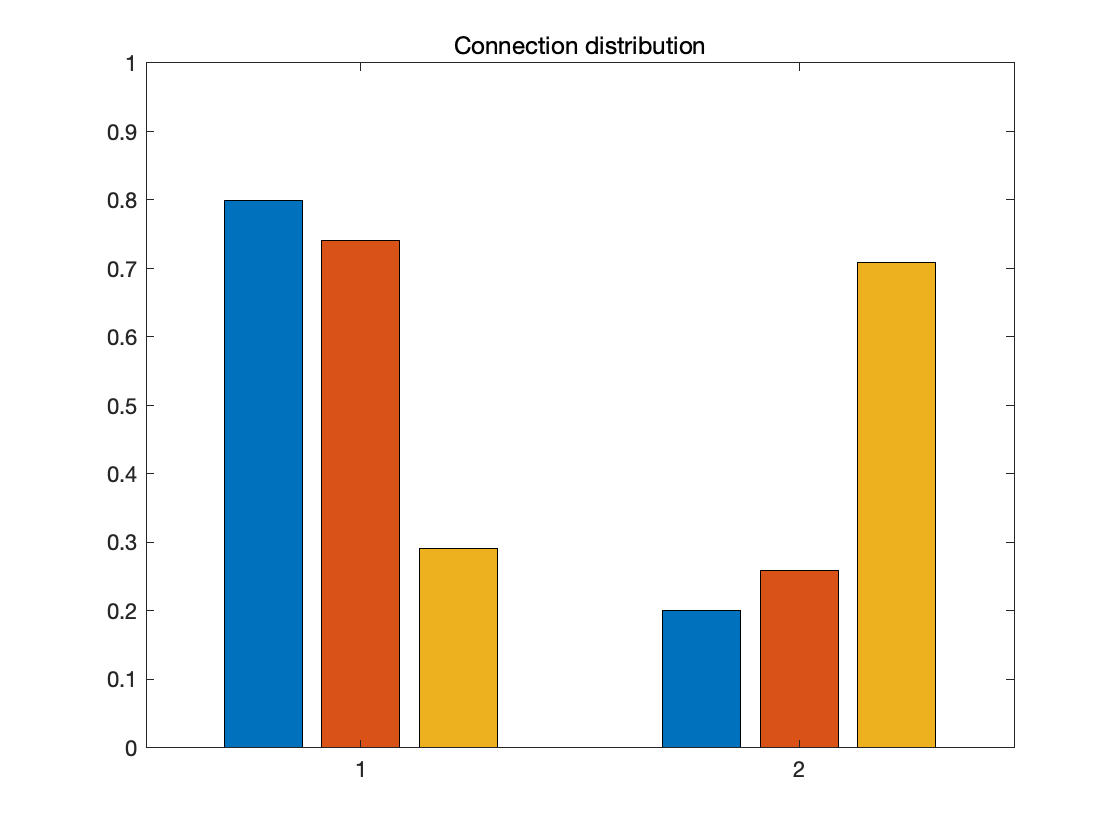


con = con ./ sum(net_mean, "all");

% plot connection distribution
figure
bar(con, 'grouped')
ylim([0 1])
title('Connection distribution')

function data = threshold_net(data, p, thr_type, net_type)
% threshold 2D or 3D network
% Input:
%           data: inputed network
%           p: weight
%           thr_type: "Mix" keep half the strongest and weakest connections
%                     "low" keep the weakest connections.
%                     "high" keep the strongest connections.
%           net_type: "binary" converted to binarized network
% Output:
%           data: thresholded network


for i = 1:size(data, 3)
    
    net_win = data(:, :, i);
    net_win = tril(net_win);
    n = size(net_win, 1);                                %number of nodes
    net_win(1:n+1:end) = 0;                             %clear diagonal
    ind = find(net_win);                                %find all links
    E = sortrows([ind net_win(ind)], -2, "descend");               %sort by magnitude
    E = E(1:end, :);
    en = round((n ^ 2 - n) * (p / 2));                                 %number of links to be preserved
    
    if rem(en, 2) && isequal(net_win, net_win.')              %if symmetric matrix
        en = en + 1;                                         %ensure symmetry is preserved
    end
    
    % select links according to network mode
    if thr_type == "mix"
        
        E = E(en / 2 + 1: end - en / 2, 1);
        
    elseif thr_type == "low"
        
        E = E(1: end - en, 1);
        
    elseif thr_type == "high"
        
        E = E(en + 1:end, 1);
        
    end
    
    
    net_win(E) = 0;
    net_win = net_win + net_win';
    
    data(:, :, i) = net_win;
    
end

if net_type == "binary"
    
    data(data ~= 0) = 1;
    
end

end